# Segmentació per K-means

openExample('images/KMeansSegmentationExample')

## Netejar l'entorn

clc;
close all;
clear variables;

## Step 1: Read Image

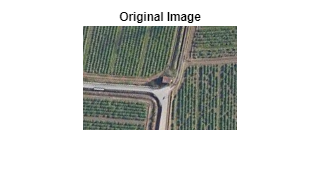

%img = imread("DemoPratFullAlt.png"); % 3 colors és ok
img = imread("DemoPratFullAltMini.png"); % 2 colors és ok
%img = imread("DemoPratFullAltMicro.png"); % 2 colors és ok

figure
imshow(img), title("Original Image");

## Step 2: Classify Colors in RBG Color Space Using K-Means Clustering

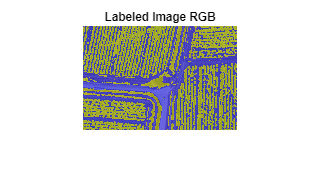

numColors = 2;
L = imsegkmeans(img, numColors);
B = labeloverlay(img, L);

figure
imshow(B), title("Labeled Image RGB");

## Step 3: Convert Image from RGB Color Space to L*a*b* Color Space

The L*a*b* space consists of:

1) The luminosity layer L*.

2) The chromaticity  layer a* that indicates where a color falls along the red-green axis.

3) The chromaticity layer b* that indicates where a color falls along  the blue-yellow axis.

lab_img = rgb2lab(img);

## Step 4: Classify Colors in a*b* Space Using K-Means Clustering

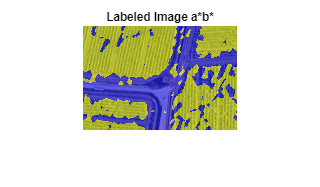

ab = lab_img(:, :, 2:3);
ab = im2single(ab);
pixel_labels = imsegkmeans(ab, numColors, NumAttempts = 5);

B2 = labeloverlay(img, pixel_labels);

figure
imshow(B2), title("Labeled Image a*b*");

## Step 5: Create Images that Segment Image by Color

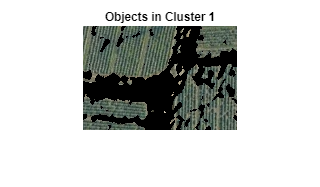

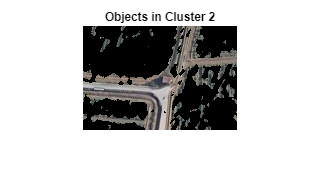

mask = zeros([size(pixel_labels) numColors]);

for i = 1:numColors

    mask(:,:,i) = pixel_labels == i;
    cluster = img.*uint8(mask(:,:,i));
    
    figure
    imshow(cluster), title("Objects in Cluster " + i);

end

## Step 6: Segment field

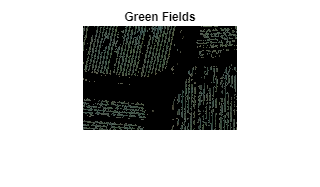

green_mask_i = 1;

L = lab_img(:, :, 1);
L_green = L.*double(mask(:,:,green_mask_i));
L_green = rescale(L_green);
idx_light_green = imbinarize(nonzeros(L_green));

green_idx = find(mask(:,:,green_mask_i));
mask_dark_green = mask(:,:,green_mask_i);
mask_dark_green(green_idx(idx_light_green)) = 0;

green_fields = img.*uint8(mask_dark_green);

figure
imshow(green_fields), title("Green Fields");